# Survey of Proposed Test Methods for IEC 62563-3

## 1. Background

This is the commonly seen **CIE chromaticity diagram** on a plane spanned by CIEXYZ $x$ and $y$, where $0 \le x \le1$ and $0 \le y \le 1$.

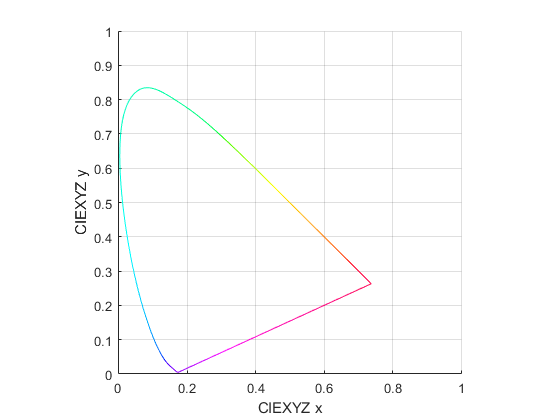

sRGB = RGB_in_xyY;
clf; sRGB.spectral_locus_color
xlabel('CIEXYZ x')
ylabel('CIEXYZ y')
grid on; snapnow

We can add a 3rd dimension, CIEXYZ $Y$ (i.e., luminance), to form a three-dimensional color space (i.e., **CIE xyY**) to indicate any color (tristimulus).

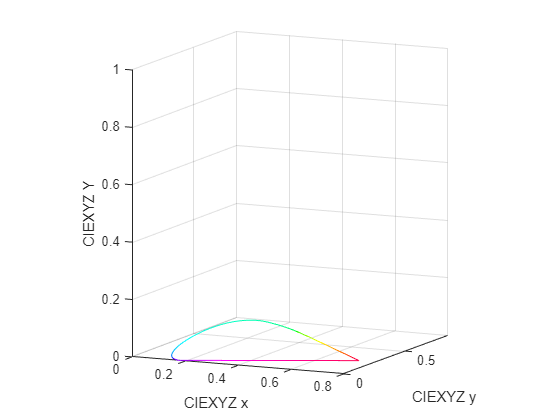

clf; sRGB.spectral_locus_color
xlabel('CIEXYZ x')
ylabel('CIEXYZ y')
zlabel('CIEXYZ Y')
axis([0 0.8 0 0.85 0 1])
view(25,10)
grid on
rotate3d on; snapnow

In monochrome imaging, we usually consider a one-dimensional axis in the CIEXYZ Y direction in this CIE xyY color space. For example, the following figure shows 15 measurement points (gray-shaded balls) from characterizing a monochrome display to check its comformity with DICOM GSDF. In this test, we need to check its maximum value (***Lmax***), minimum value (***Lmin***), and the transition from the minimum to the maximum (***gamma ***or ***EOTF***). Basically we examine the data points' relative locations *vertically*.

Notice that the *Lmin* is seldom zero for multiple reasons. In other words, a dark monochrome display still emits light.

In IDMS 1.1, the test methods for Lmax, Lmin, and gamma are IDMS1.1-5.3, IDMS1.1-5.6, and IDMS1.1-6.1, respectively.

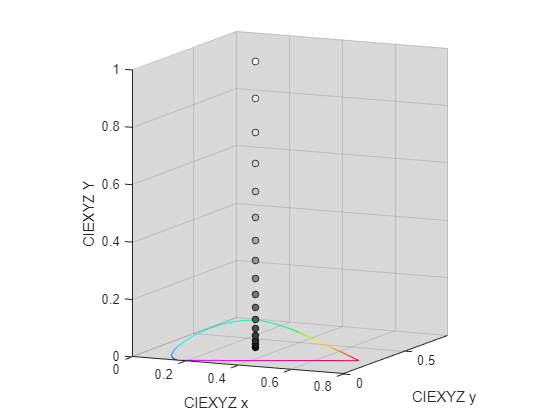

clf; sRGB.draw_grayscale; snapnow

Sometimes we want to check the chromaticity of the monochrome display (e.g., **white point** or color temperature) or whether the gray shades have identicial chromaticity (i.e., **gray tracking**). We can view these data points from the top and check their locations on the CIEXYZ x-y plane *horizontally*. 

In IDMS 1.1, the test method for white point is IDMS1.1-5.19. The test method for gray tracking is IDMS1.1-6.15.

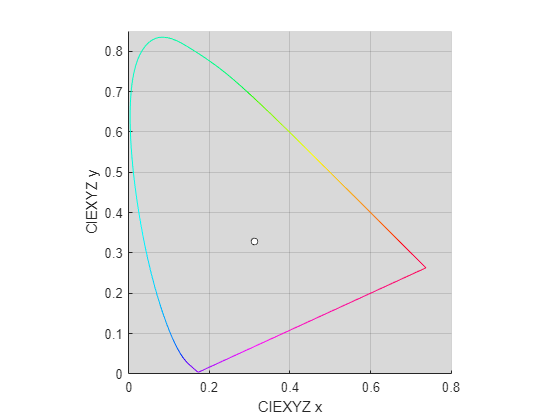

view(0,90); snapnow

Color displays have three primary colors instead of grayscales. Therefore, we look at three vertical pillars instead of one. The following figure shows 15 measurement points of the red, green, and blue channels. The three pillars have different height because for the same DDL, the luminance varies among the R, G, and B channels. Notice that the grayscales need to be generated by adding the three channels at a specific ratio. For the sRGB color space, the ratio is $21:72:7$. **Additivity** of the RGB channels is another important factor when characterizing a display.

Also notice that all 15 red shades are perfectly aligned vertically and so do the green and blue shades. This is usually unrealistic because the other two channels are dark but may still emit light. The light leaked from the other two channels will contaminate the primary color and reduce its chroma (i.e., pulling it toward the center). 

Similarly, we can discuss the maximum, minimum, and transition from the minimum to the maximum of the three primary colors. We can measure the **maximum luminance of the RGB channels**, because it determines the maximum luminance of the display as well as its white point. We can also measure the **gamma for each RGB channel** because it is the basis of characterizing a display. The minimum of the RGB channels is identical to Lmin. 

In IDMS 1.1, the test method for the primary maximum is IDMS1.1-5.14. The test method for the primary gamma is IDMS1.1-6.2. The test method for additivity of primaries is IDMS1.1-6.10.

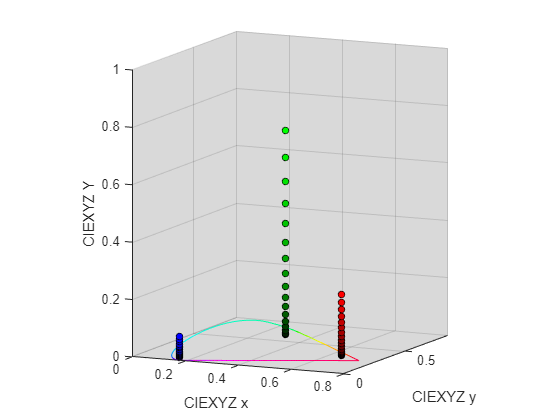

clf; sRGB.draw_colorscale; snapnow

Again, we can examine the three primary colors from the top to determine their chromaticity (*horizontally*). Notice that in this figure, all 15 red shades overlap perfectly and so do the green and blue shades, and this is not usually the case especially for LCDs.

Similarly, we want to know the **chromaticity of the primary colors** and whether the primary shades have identicial chromaticity (i.e., **color tracking**).

In IDMS 1.1, the test method for the primary maximum is also defined in IDMS1.1-5.14. However, IDMS does not provide a method for determining the color tracking.

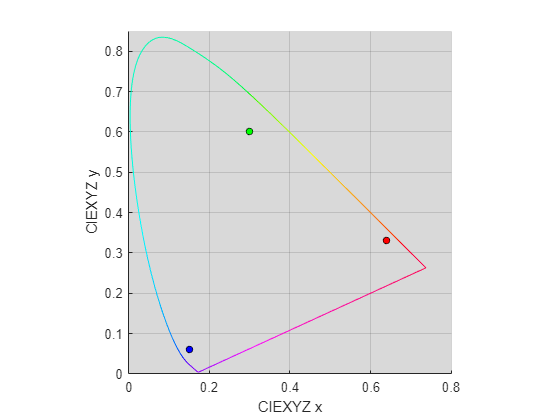

view(0,90); snapnow

Mixing the three channels at different ratios will generate different colors and form a three-dimensional **color gamut volume**. 

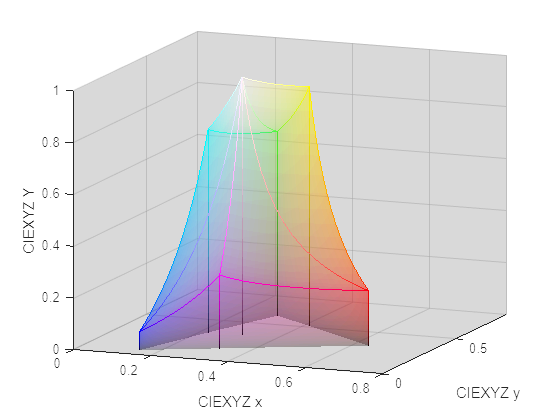

clf; sRGB.sRGB_in_xyY; snapnow

When we look at the color gamut volume from the top, what we see is just a triangle. This two-dimensional representation tells us the widest perimeter of the color gamut volume only, but not the shape below it. As a result, it is frequently arguable whether to measure the color gamut using the straight-forward two-dimensional triangle or the more complicated three-dimensional color gamut volume.

In IDMS 1.1, the test method using the 2D color gamut area is IDMS1.1-5.18.1. The test method using the 3D color gamut volume is IDMS1.1-5.32.

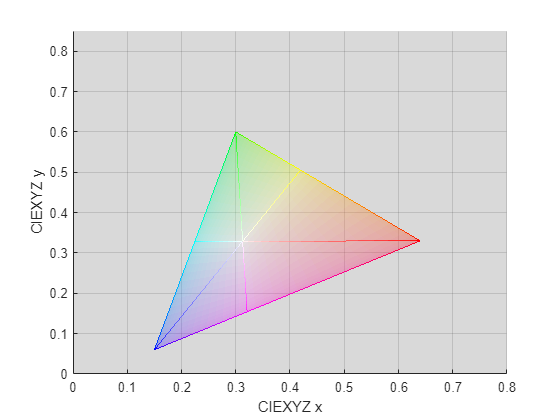

view(0,90); snapnow

The following chart summarizes the abovementioned IDMS test methods.

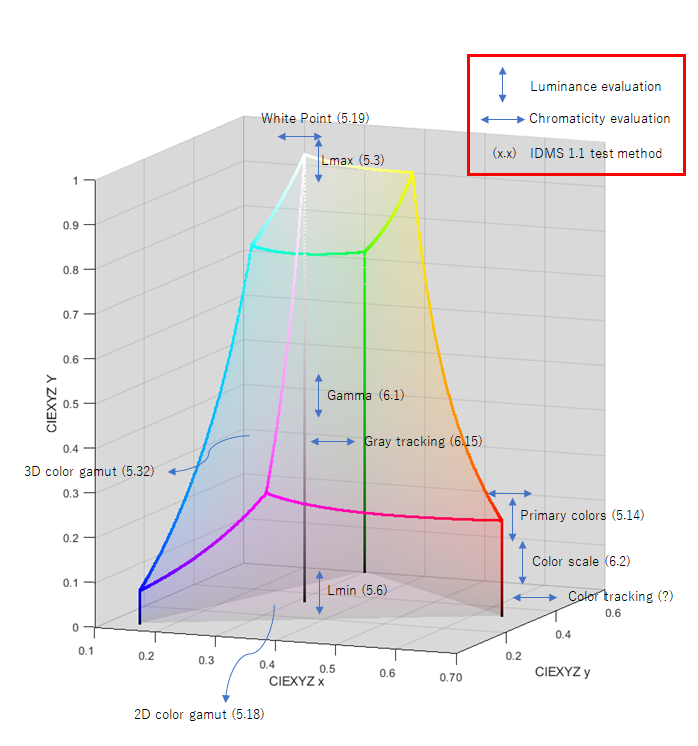

## 2. Test methods

Ota-san collected 7 color space-related test methods proposed by WG51 members. Each test method can be decomposed into "**what to measure**" and "**what to expect**". If we consider only the "what to measure" part, the proposed test methods can be classified in the following table with corresponding IDMS test methods.

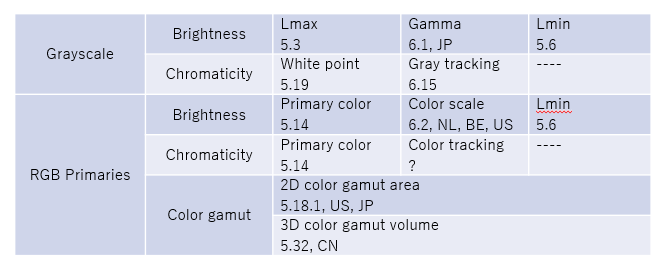

This table has not included the 6x6x6 sampling test proposed by BE and the POUQA method mentioned by Craig. 